# Problem 3

Given the BVP problem


$$\displaystyle\qquad
\sigma\frac{\partial u}{\partial t} - \frac{\partial }{\partial x}\left(
x\frac{\partial u}{\partial x}\right) = 0,\qquad 1\le x\le 2,\quad t\ge 1,$$


with boundary conditions


$$\displaystyle\qquad
u(t,1) = 1,\qquad u(t,2) = -49.0,\qquad t\ge 0,$$


and initial condition


$$\displaystyle\qquad
u(0,x) = 1 + 50\cos\left(\frac{\pi x}{2}\right),\qquad 1\le x\le 2,$$


following Practice **P2.3**, we want to compute its FEM solution with 500 divisions of the domain $\Omega = [1,2]$ for both, the stationary $(\sigma = 0$) and the transient case (with $\sigma = 1$). For the latter, use the Crank Nicolson method ($\alpha = 1/2$) to integrate the time-ODE system for $t_{\text{ini}} = 0$ to $t_{\text{fin}} = 0.2$ taking a time step $\Delta t = 0.01$. From the FEM solutions found, answer the following questions:

clearvars
close all
clc
format short e

## (a) [4 points]

Compute the stationary solution and, as we did in Practice **P2.2**, give the error, $\varepsilon$, when comparing the numerical solution with the exact solution


$$\displaystyle\qquad
\tilde{u}(x) = -\frac{50}{\log 2}\log x + 1,$$


and we define $\varepsilon$ as


$$\displaystyle\qquad
\varepsilon = \| \tilde{u}(x) - u_{\text{num}}\| = \max\limits_{k=1,\dots,n}|\tilde{u}(x_{k}) 
   - u_{\text{num}}(x_{k})\|,$$


- 1.5225e-06$\surd$

- 1.3043e-06

- 1.5923e-06

- 1.1764e-06

- Leave it empty (no penalty)

Hint. The nodal value of the stationary solution at node 120 is $u_{120} =$-1.4401e+01


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% DATA
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = 50.0;
numDiv = 500;
tini = 0.0;
tfin = 0.2;
dt = 0.01;
numNodHint = 120;

a = 1; b = 2; % Domain a < x < b
xp = sqrt(3);
g = @(x) 1 + A*cos(pi*x/2);
uA = g(a); uB=g(b);

% Exact solution
u_exact = @(x) (uB - uA)*log(x)/log(2) + uA;

alpha = 0.5;  %Crank Nicolson
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

a1 = 1.0;
a2 = 1.0; %Coefficient a2
h = (b-a)/numDiv; %length of the elements

nodes = (a:h:b)'; %nodes
elem = [1:numDiv; 2:numDiv+1]'; %connectivity natrix: linear elements

numNod = size(nodes,1);   %find out number of nodes
numElem = size(elem, 1);  %find out number of elements
if numNodHint > numNod
    error(...
        ['number of node in the hint Hint (%d) ',...
         'grater than number of nodes (%d)'],...
        numNodHint, numNod)
else
   nodeHint = nodes(numNodHint);
end

t = (tini:dt:tfin)';  %Time ticks at which the (apprximate) transient 
                      % solution is % computed
numTimeTicks = size(t,1); %Number of time-ticks

%Assembly of global matrices
K = zeros(numNod);        %initialise the global stifness matrix 
M = zeros(numNod);        %initialise the global mass matrix
F = zeros(numNod,1);      %initialise the global vector F
                          %(not necessary here)

Me = a2*h*[2, 1; 1, 2]/6; %local mass matrix (the same for all elements!)
% Me = a2*h*[1,0;0,1]/2;  %mass lumping

for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    x1 = nodes(elem(e,1)); %Position of the 1st node of the element
    x2 = nodes(elem(e,2)); %Positionof the 2nd node of the element
    Ke = 0.5*a1*(x1+x2)*[1,-1;-1,1]/h;
    %Assembly of the stiffness matrices
    K(rows,cols) = K(rows,cols) + Ke;
    M(rows,cols) = M(rows,cols) + Me;
    %Assembly of the F terms (not necessary here)
    %Fe=h/6.0*[2*x1+x2;x1+2*x2];
    %F(rows) = F(rows) + Fe;
end

%Boundary conditions (BC)
fixedNodes = [1, numNod]; %Fixed nodes (nodes where u is fixed)
freeNodes = setdiff(1:numNod, fixedNodes);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          Stationary Solution                            %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Boundary Conditions (BC): Natural BC
Q = zeros(numNod,1);
uStat = zeros(numNod,1);
Q(freeNodes) = 0; %Not necessary, since Q has been initalised to 0.

%Boundary Conditions (BC): Essential BC
uStat(1) = uA; uStat(numNod) = uB;

%Reduced system
Fm = Q(freeNodes)-K(freeNodes,fixedNodes)*uStat(fixedNodes);
Km = K(freeNodes,freeNodes);

%Solve the reduced system
um = Km\Fm;
uStat(freeNodes) = um;

%
% Part A
%
u = u_exact(nodes);
epsilon = norm(u-uStat, inf);
u_stat_hint = uStat(numNodHint);
fprintf(['Part A\n',...
    'Error for the stationary solution: eps = |u(x_k)-u_k| = %9.4e\n',...
    'Hint: the stationary FEM solution at node k = %d\n ',...
    '\tis u(%d) = %9.4e\n'],...
    epsilon,numNodHint,numNodHint,u_stat_hint)

Part A
Error for the stationary solution: eps = |u(x_k)-u_k| = 1.5225e-06
Hint: the stationary FEM solution at node k = 120
 	is u(120) = -1.4401e+01


### **Solution of part (a)**

$\varepsilon=$1.5225e-6$\triangleright$

## (b) [3 points]

Approximate the stationary solution at the point $x_{p} = \sqrt{3}$ by linear interpolation from the nodal solution using the element’s nodes to which the point belongs. The result is: 

- -3.8624e+01$\surd$

- -4.3336e+01

- -4.3142e+01

- -4.1355e+01

- Leave it empty (no penalty)

%
% Part B
%
u_interp = interp1(nodes,uStat,xp); 
fprintf(['Part B\n',...
    'Interpolated value of the stationary solution at x = %9.4e\n',...
    '\tis u_interp = %9.4e\n'],xp,u_interp)

Part B
Interpolated value of the stationary solution at x = 1.7321e+00
	is u_interp = -3.8624e+01


### **Solution of part (b)**

$u_{\text{interp}}=$-3.8624e+01$\triangleright$

## (c) [3 points]

 Finally, from the transient solution $u_{t}$ for this problem (according to the previous set values), give the mean of all the nodal values

- -2.7075e+01$\surd$

- -2.7046e+01

- -2.4390e+01

- -2.4886e+01

- Leave it empty (no penalty)

Hint. The value in the final transient solution at node 120 is $u_{t}(120) =$−1.4668e+01

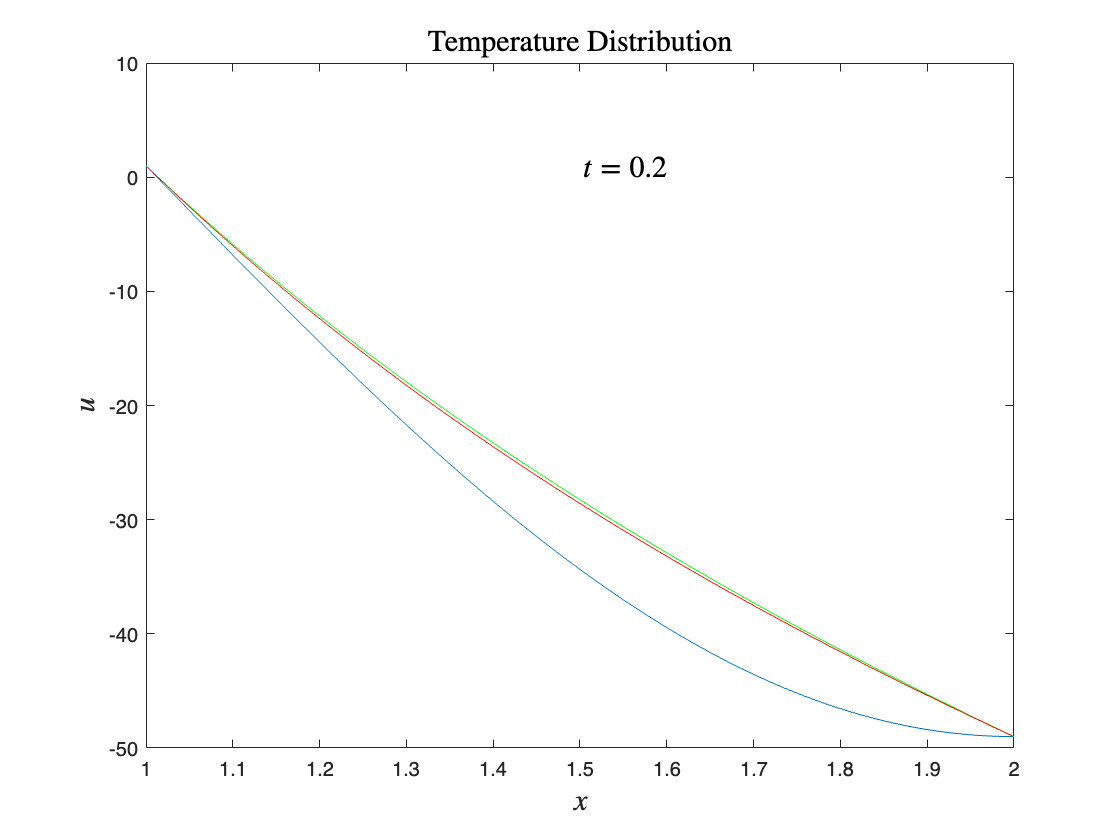

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          Transient Solution                             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Q = zeros(numNod,1); %Initialize global Q vector

%Initial Conditions for the transient solution
u = g(nodes);

%
% System of equations (see eq. 4)
%
Qm = Q(freeNodes)-K(freeNodes,fixedNodes)*uStat(fixedNodes);
Am = M(freeNodes,freeNodes)+dt*alpha*K(freeNodes,freeNodes);
Bm = M(freeNodes,freeNodes)-dt*(1-alpha)*K(freeNodes,freeNodes);
Fm = dt*Qm;
u_t = u(freeNodes);

%Plot curve
plot(nodes, u);
title('Temperature Distribution', 'interpreter','LaTeX','FontSize',15)
xlabel('$x$', 'Interpreter','LaTeX','FontSize',15)
ylabel('$u$','Interpreter','LaTeX','FontSize',15)
hold on
plot(nodes, uStat, 'g') %Plot stationary solution
%Solve the system at each time step
%for i = 1:length(t) % (Should be 2:length(t))
for i = 2:length(t) 
    u_dt = Am\(Bm*u_t+Fm);
    u_t = u_dt;
    %plot curve
        ff = plot(nodes(freeNodes), u_t,'-r');
        tt = text(1.5, max(u_t), ['$t = $' num2str(t(i))],...
            'interpreter','LaTex','FontSize',15);
        drawnow;
        pause(0.05)
        delete(tt);
        delete(ff);
end
plot(nodes(freeNodes), u_t, '-r');
text(1.5, max(u_t),  ['$t = $' num2str(t(i))],...
    'interpreter','LaTex','FontSize',15); 
hold off

u(freeNodes) = u_t; %Now u holds the nodal solution at t = tfin
% 
% Part C
%
% For the transient solution, taking $\sigma = 1$, give the nodal
% averaged value of u at t=tfin, i.e.
%
% <u>_tfin = sum(u_k(tfin), k=1,...,n)
%
u_av = sum(u)/numNod;
u_hint = u(numNodHint);
fprintf(['Part C\n',...
         '< u >_(t = %f) = %9.4e\n',...
         'Hint. the value at t = %f of the transient solution at node\n',...
         '\tk = %d is u(%d) = %9.4e\n\n'],...
         tfin,u_av,tfin,numNodHint,numNodHint,u_hint)

Part C
< u >_(t = 0.200000) = -2.7075e+01
Hint. the value at t = 0.200000 of the transient solution at node
	k = 120 is u(120) = -1.4668e+01



### **Solution of part (c)**

$\langle u_{t = 0.2}\rangle =$ -2.7075e+01$\triangleright$

## Misc

Compare the difference between the two solutions

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Misc
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Precision: compare the difference between the two solutions
errorTemp = norm(uStat(freeNodes)-u_t, inf);
fprintf('Misc. Error for the stationary and the transient solution\n')

Misc. Error for the stationary and the transient solution


fprintf("at tfin = %e: error = ||uStat - u||_Inf = %10.5e\n",...
    tfin, errorTemp)

at tfin = 2.000000e-01: error = ||uStat - u||_Inf = 3.40506e-01
